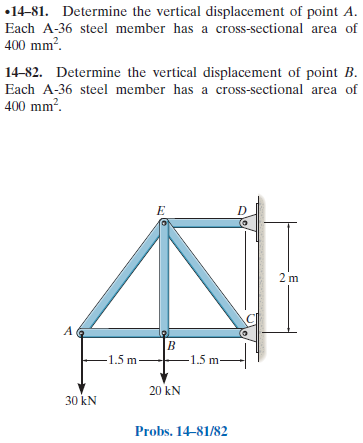

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(2/1.5))*u.deg;
jointA = [-3 0]*u.m;
jointB = [-1.5 0]*u.m;
jointC = [0 0]*u.m;
jointD = [0 2]*u.m;
jointE = [-1.5 2]*u.m;

# member data

E = 200*u.GPa;
A = 400*u.mm^2;

# truss

t = Truss;
t = t.add('reaction', 'Rc', {'Rcx' 'Rcy'}, jointC);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pa', [0 -30]*u.kN, jointA);
t = t.add('concentrated', 'Pb', [0 -20]*u.kN, jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fae', jointA, jointE, E, A);
t = t.add('member', 'Fbe', jointB, jointE, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fce', jointC, jointE, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 3) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0.844\,\mathrm{mm}\\ \mathrm{vA} & -6.23\,\mathrm{mm}\\ \mathrm{uB} & 0.422\,\mathrm{mm}\\ \mathrm{vB} & -3.79\,\mathrm{mm}\\ \mathrm{uC} & 0\\ \mathrm{vC} & 0\\ \mathrm{uD} & 0\\ \mathrm{vD} & 0\\ \mathrm{uE} & -1.12\,\mathrm{mm}\\ \mathrm{vE} & -3.29\,\mathrm{mm} \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & -22.5\,\mathrm{kN}\\ \mathrm{Fae} & 37.5\,\mathrm{kN}\\ \mathrm{Fbe} & 20.0\,\mathrm{kN}\\ \mathrm{Fbc} & -22.5\,\mathrm{kN}\\ \mathrm{Fce} & -62.5\,\mathrm{kN}\\ \mathrm{Fde} & 60.0\,\mathrm{kN} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Rc} & -60\,\mathrm{kN} & 50\,\mathrm{kN} & 0\\ \mathrm{Rd} & 60\,\mathrm{kN} & 0 & 0\\ \mathrm{Pa} & 0 & -30\,\mathrm{kN} & 0\\ \mathrm{Pb} & 0 & -20\,\mathrm{kN} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & -22.5\,\mathrm{kN} & 0 & 0\\ \mathrm{Fae} & 22.5\,\mathrm{kN} & 30.0\,\mathrm{kN} & 0\\ \mathrm{Fbe} & 0 & 20.0\,\mathrm{kN} & 0\\ \mathrm{Fbc} & -22.5\,\mathrm{kN} & 0 & 0\\ \mathrm{Fce} & 37.5\,\mathrm{kN} & -50.0\,\mathrm{kN} & 0\\ \mathrm{Fde} & -60.0\,\mathrm{kN} & 0 & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 4) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Rc} & 78.1\,\mathrm{kN}\\ \mathrm{Rd} & 60.0\,\mathrm{kN}\\ \mathrm{Pa} & 30.0\,\mathrm{kN}\\ \mathrm{Pb} & 20.0\,\mathrm{kN} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fae} & 0\\ \mathrm{Fbe} & 30\,\mathrm{kN}\,m\\ \mathrm{Fbc} & 0\\ \mathrm{Fce} & 150\,\mathrm{kN}\,m\\ \mathrm{Fde} & 120\,\mathrm{kN}\,m \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Rc} & 0 & 0 & 150\,\mathrm{kN}\,m\\ \mathrm{Rd} & 0 & 0 & -120\,\mathrm{kN}\,m\\ \mathrm{Pa} & 0 & 0 & 0\\ \mathrm{Pb} & 0 & 0 & -30\,\mathrm{kN}\,m \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fae} & 0 & 0 & 0\\ \mathrm{Fbe} & 0 & 0 & 30\,\mathrm{kN}\,m\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fce} & 0 & 0 & -150\,\mathrm{kN}\,m\\ \mathrm{Fde} & 0 & 0 & 120\,\mathrm{kN}\,m \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Rc} & 150\,\mathrm{kN}\,m\\ \mathrm{Rd} & 120\,\mathrm{kN}\,m\\ \mathrm{Pa} & 0\\ \mathrm{Pb} & 30\,\mathrm{kN}\,m \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa la_f_c ma_f_c_vpa la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;